# Regresión lineal por minimos cuadrados

#### 2.a

%t0 = input('\n Ingrese el tiempo inicial: ');
% Datos experimentales capturados
n=input('\n Cuantos datos deseas ingresar: ')
for i=1:n
    x = fprintf("Dame los datos de x: "[i]);
end
x = input([]) %[2012,2013,2014,2015,2016,2017];

Error using input
The first argument to INPUT must be a string or character vector.

y = input([]) %[10,10.9,11.7,12.6,13.8,14.9];


% Calcular n, x^2, xy, y las sumatorias correspondientes.
n =  length(x);
x2 = x.^2;
xy = x.*y;
Sxy = sum(xy);
Sy = sum(y);
Sx = sum(x);
Sx2 = sum(x2);
% Calcular el valor para "a" y para "b".
a = (n*Sxy-Sx*Sy) / (n*Sx2-(Sx)^2);
b = (Sy-a*Sx) / (n);

% Construir la función anónima f(x) = a*x + b;
f = @(x) a*x + b;
disp(f(x));

    9.8810   10.8552   11.8295   12.8038   13.7781   14.7524



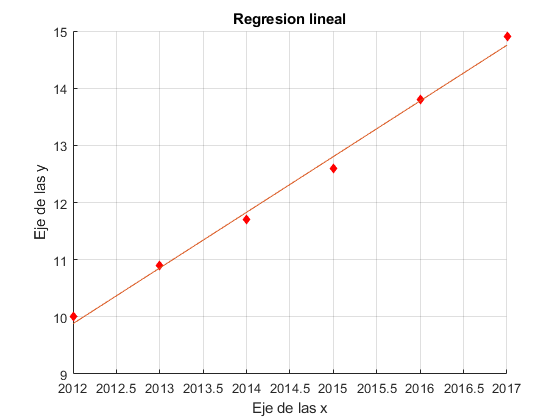

% Ahora graficamos los puntos experimentales con la función scatter y el modelo de regresión lineal.
scatter(x,y,30,"red","filled","diamond");
hold on;
plot(x,f(x));
hold off;
grid on;
xlabel("Eje de las x");
ylabel("Eje de las y");
title("Regresion lineal");

#### 2.b

# Regresión Polinomial

#### 1

#### 2

#### Función Regresión Lineal

#### Función Regresión Polinomial